# ความน่าจะเป็นและสัญญาณสุ่ม (Probability & Random Signal)

# ตอนที่ 7 : เวกเตอร์สุ่ม (Random Vector)

ในกรณ๊ที่เรามีตัวแปรสุ่มมากกว่าหนึ่งตัว** เราสามารถจัดเรียงตัวแปรเหล่านี้ให้อยู่ในรูปของเวกเตอร์ **เราจะกำหนดให้ ตัวแปรสุ่มมีทั้งหมด $n$ ตัว และกำหนดให้เวกเตอร์สุ่ม (random vector) $\mathbf{X}$ ประกอบไปด้วยสมาชิกดังนี้


$$\mathbf{X}=\left\lbrack \begin{array}{c}
X_1 \\
\vdots \\
X_n 
\end{array}\right\rbrack$$


หากตัวแปรสุ่มแต่ละตัวเป็นแบบไม่ต่อเนื่อง เราสามารถจำลองความไม่แน่นอนของเวกเตอร์ดังกล่าวได้ว่าการแจกแจงซึ่งมีหลากหลายรูปแบบ ซึ่งล้วนแต่ต้องเขียนอยู่ในรูปของฟังก์ชันต่อไปนี้ 


$$\mathrm{P}\left(\mathbf{X}\in A\right)=\sum_{\mathbf{x}\in A} \cdots \sum f_{\mathit{\mathbf{X}}} \left(\mathbf{x}\right)$$


โดยที่


$$\begin{array}{l}
\sum_{\mathrm{for}\;\mathrm{all}\;\mathbf{x}} \cdots \sum f_{\mathbf{X}} \left(\mathbf{x}\right)=1\\
0\le f_{\mathbf{X}} \left(\mathbf{x}\right)\le 1
\end{array}$$


หากตัวแปรสุ่มแต่ละตัวเป็นแบบต่อเนื่อง เราสามารถเขียนฟังก์ชันแจกแจงได้ในรูปแบบดังต่อไปนี้


$$\mathrm{P}\left(\mathbf{X}\in A\right)=\int^A \left\lbrace \cdots \int \left\lbrace f_{\mathit{\mathbf{X}}} \left(x_1 ,\cdots ,x_n \right)\right\rbrace \;\mathrm{d}\;x_1 \cdots \right\rbrace \;\mathrm{d}\;x_n$$


โดยที่


$$\begin{array}{l}
\int_{-\infty }^{\infty } \left\lbrace \cdots \int_{-\infty }^{\infty } \left\lbrace f_{\mathit{\mathbf{X}}} \left(x_1 ,\cdots ,x_n \right)\right\rbrace \;\mathrm{d}\;x_1 \cdots \right\rbrace \;\mathrm{d}\;x_n =1\\
0\le f_{\mathbf{X}} \left(\mathbf{x}\right)\le 1
\end{array}$$


ถ**ึงแม้เวกเตอร์สุ่มเป็นเวกเตอร์หลัก (column) ในการเขียนสมการคณิตศาสตร์ แต่ในการเขียนโปรแกรมส่วนใหญ๋ เรามักจะเรียกเวกเตอร์ให้เป็นแนวนอนเพื่อที่จะให้ค่าของเวกเตอร์นั้นเรียงกันได้ในแนวตั้ง** เช่น กำหนดให้ตัวแปรสุ่มมีทั้งหมด 3 ตัวซึ่งจะถูกเก็บค่า/สุ่มค่าทั้งหมด 4 ครั้ง เราจะได้ชุดข้อมูลในรูปแบบดังกล่าว

 
$$\mathrm{ข้อมูล}:\left\lbrack \begin{array}{cccc}
{\mathbf{X}}_{\left(1\right)}  & {\mathbf{X}}_{\left(2\right)}  & {\mathbf{X}}_{\left(3\right)}  & {\mathbf{X}}_{\left(4\right)} 
\end{array}\right\rbrack$$


ซึ่งสามารถเขียนเป็นโปรแกรมได้ดังนี้

X = rand(4,3) % uniform distribution between 0 & 1

X =     0.4844    0.8296    0.2297
    0.0274    0.5490    0.5741
    0.9214    0.1532    0.9114
    0.5770    0.2602    0.5215


## ค่าคาดหวังและเมตริกซ์แปรปรวน

ไม่ว่าการกระจายตัวจะเป็นอย่างไร เราสามารถที่จะจำลองลักษณะความไม่แน่นอนจากคุณลักษณะต่างๆได้ หนึ่งในนั้นก็คือ**ค่าคาดหวังของเวกเตอร์สุ่ม**ซึ่งเท่ากับเวกเตอร์ของค่าคาดหวังของแต่ละสมาชิกในเวกเตอร์


$$\mu_{\mathbf{X}} =E\left\lbrace \mathbf{X}\right\rbrace =\left\lbrack \begin{array}{c}
E\left\lbrace X_1 \right\rbrace \\
\vdots \\
E\left\lbrace X_n \right\rbrace 
\end{array}\right\rbrack$$


นอกจากนี้ เรายังสามารถอธิบายความแปรปรวนของเวกเตอร์สุ่มได้ เช่นเดียวกันกับกรณีของตัวแปรสุ่มสองตัว เราจำเป็นที่จะต้องจับคู่ระหว่างตัวแปรสุ่มเพื่อคำนวณหาค่าแปรปรวนร่วมเดี่ยวและยังต้องหาค่าแปรปรวนของแต่ละตัวแปรสุ่มอีกด้วย

หากเรามีจำนวนตัวแปรสุ่มทั้งหมด $n$ ตัวด้วยกัน เราจะมีค่าแปรปรวนทั้งหมด $n$ ตัว ($\sigma_{X_i }^2$) และค่าแปรปรวนร่วมเกี่ยวเป็นจำนวนทั้งหมด $n\cdot \left(n-1\right)$ ตัว ($\sigma_{X_i X_j }$) เพื่อความสะดวกในการเขียนอธิบาย **เราสามารถจัดค่าแปรปรวนทั้งหมดนี้ให้อยู่ในรูปของเมตริกซ์ดังต่อไปนี้**


$${\mathbf{K}}_{\mathbf{X}} =\mathrm{Cov}\left\lbrace \mathbf{X},\mathbf{X}\right\rbrace =\left\lbrack \begin{array}{cccc}
\sigma_{X_1 }^2  & \sigma_{X_1 X_2 }  & \cdots  & \sigma_{X_1 X_n } \\
\sigma_{X_1 X_2 }  & \sigma_{X_2 }^2  & \cdots  & \sigma_{X_2 X_n } \\
\vdots  & \vdots  & \ddots  & \vdots \\
\sigma_{X_1 X_n }  & \sigma_{X_2 X_n }  & \cdots  & \sigma_{X_n }^2 
\end{array}\right\rbrack$$


**เมตริกซ์นี้ถูกเรียกว่า เมตริกซ์ค่าแปรปรวน-ค่าแปรปรวนร่วมเกี่ยว** หรือเรียกสั้นๆว่า **เมติกซ์ค่าแปรปรวนร่วมเกี่ยว **(variance-covariance matrix/covariance matrix) ซึ่งเมตริกซ์นี้จะมีคุณสมบัติดังต่อไปนี้


$${\mathbf{v}}^{\top } \cdot {\mathbf{K}}_{\mathbf{X}} \cdot \mathbf{v}\ge 0$$



$${\mathbf{K}}_{\mathbf{X}} ={\mathbf{K}}_{\mathbf{X}}^{\top }$$



$$\mathrm{Cov}\left\lbrace \mathbf{A}\cdot \mathbf{X}+\mathbf{b},\mathbf{A}\cdot \mathbf{X}+\mathbf{b}\right\rbrace =\mathbf{A}\cdot {\mathbf{K}}_{\mathbf{X}} \cdot {\mathbf{A}}^{\top }$$


สองสมบัติแรกแสดงให้เห็นว่าเราไม่สามารถที่จะเลือกจำลองเมตริกซ์ค่าแปรปรวนแบบสุ่มสี่สุ่มห้าได้

หากเรามีชุดข้อมูล เราสามารถที่จะใช้ฟังก์ชัน cov ของ MATLAB ในการหาเมตริกซ์ค่าแปรปรวนนี้ได้เลย

X_U = rand(100,2);
X = [X_U 2*X_U+0.1*(rand(size(X_U))-0.5)];

K = cov(X)

K =     0.0835   -0.0130    0.1675   -0.0251
   -0.0130    0.0865   -0.0272    0.1725
    0.1675   -0.0272    0.3370   -0.0530
   -0.0251    0.1725   -0.0530    0.3450


R = corrcoef(X); % เมตริกซ์สหสัมพันธ์

## การแจกแจงแบบปรกติหลายตัวแปร (Multivariate Normal Distribution)

การแจกแจงที่มักจะถูกใช้บ่อยครั้งในการจำลองความไม่แน่นอนที่มีหลายตัวแปรคือการแจกแจงแบบปรกติสำหรับหลายตัวแปร (Multivariate Normal Distribution) ซึ่งสามารถเขียนเป็นฟังก์ชันได้ดังนี้


$$f_{\mathbf{X}} \left(\mathbf{x}\right)=\frac{1}{\sqrt{{\left(2\pi \right)}^n \left|{\mathbf{K}}_{\mathbf{X}} \right|}}{\mathrm{e}}^{-\frac{1}{2}{\left(\mathbf{x}-\mu_{\mathbf{x}} \right)}^{\top } {\mathbf{K}}_{\mathbf{X}}^{-1} \left(\mathbf{x}-\mu_{\mathbf{x}} \right)}$$


**การแจกแจงนี้ถูกใช้เป็นแบบจำลองความไม่แน่นอนของพฤติกรรมหลายอย่างในระบบหุ่นยนต์เช่นความไม่แน่นอนของตำแหน่งในพื้นที่ 2 มิติ หรือความไม่แน่นอนของค่าต่างๆที่อ่านได้จากเซนเซอร์**

เราสามารถใช้ฟังก์ชัน mvnrnd ของ MATLAB ในการสุ่มค่าของตัวแปรดังต่อไปนี้ 

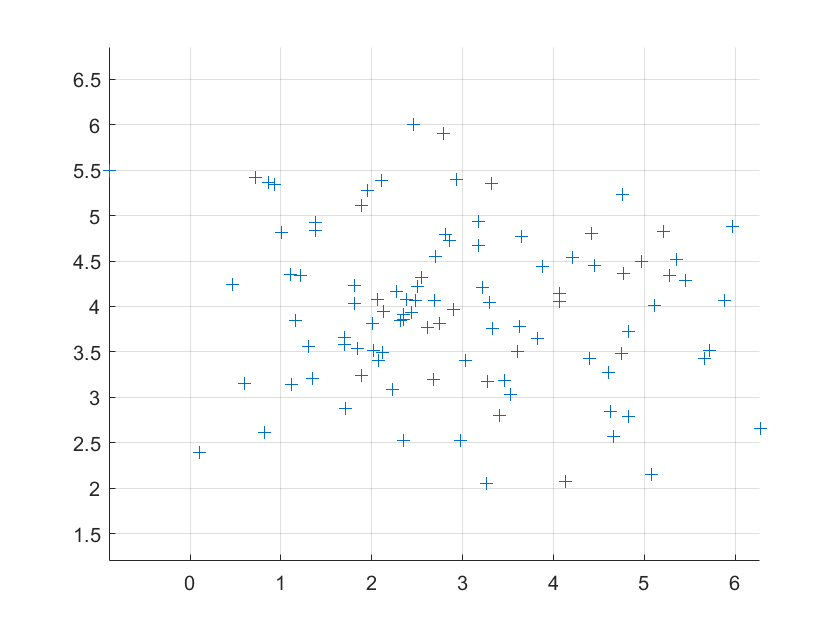

x_est = [3;4];
var = [2;1];
covar = 2*sqrt(abs(prod(var)))*(rand-1/2);
P = diag(var)+[0 covar; covar 0]; % must be semi-positive definite
X = mvnrnd(x_est,P,100);
clf
ax = axes;
hold(ax,'on')
grid(ax,'on')
plot(ax,X(:,1),X(:,2),'+')
axis(ax,'equal')